%{
ES115- Class-Project Module 1 project bank
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-14
Purpose:
    - To simulate the stopping distance of a vehicle under braking using
      time-stepped numerical methods.
    - To compare stopping distances for multiple initial velocities.
    - To visualize position, velocity, and stopping distance behavior.
    - To interpret safety implications based on braking performance.

Input:
    - Initial velocities (array of values in m/s)
    - Constant braking acceleration (negative value, m/s^2)
    - Time step size (dt)

Output:
    - Velocity vs time plots for each initial speed
    - Position vs time plots
    - Stopping distance values printed to command window
    - Comparative plot of stopping distance vs initial velocity

Engineering Algorithms:
    - Define a range of initial velocities
    - Set constant negative acceleration (braking force)
    - Use a time-stepping loop to update velocity and position:
        v_new = v_old + a*dt
        x_new = x_old + v_old*dt
    - Continue simulation until velocity reaches zero
    - Store stopping distance for each initial velocity
    - Plot velocity vs time for each case
    - Plot position vs time for each case
    - Create comparison plot of stopping distance vs initial velocity
    - Output results using fprintf
    - Interpret results (higher speed → longer stopping distance)

MATLAB tools/functions:
    - for loops, while loops
    - plot, xlabel, ylabel, title, legend, grid
    - fprintf
    - array indexing and storage
    - figure
%}

## Vehicle Braking Distance Simulator

Initial speed = 10.0 m/s → Stopping distance = 8.08 m
Initial speed = 20.0 m/s → Stopping distance = 32.83 m
Initial speed = 30.0 m/s → Stopping distance = 74.25 m


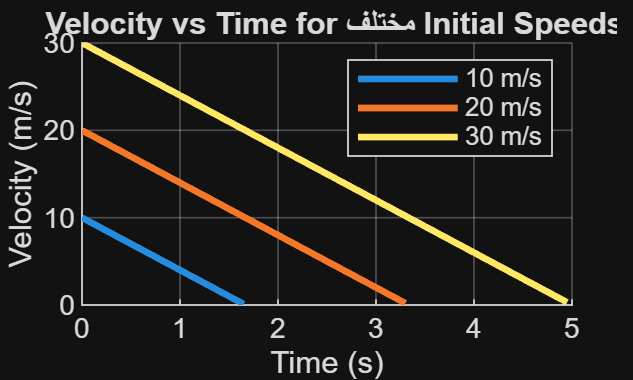

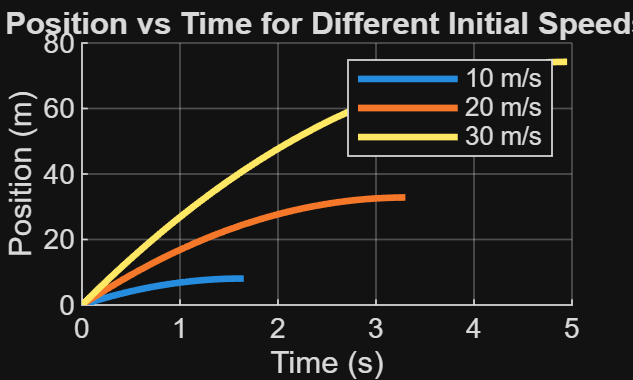

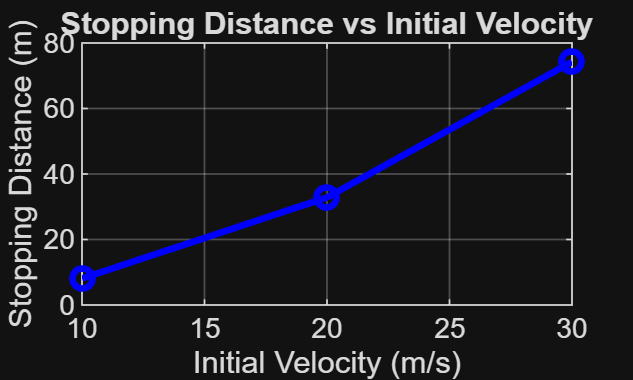

clear; clc; close all;
% Parameters
dt = 0.05;                 % time step (s)
a = -6;                    % constant braking acceleration (m/s^2)
v0_array = [10, 20, 30];   % initial velocities (m/s)
stopping_distances = zeros(size(v0_array));
figure(1); hold on;
figure(2); hold on;
% Run braking simulation for each initial speed and plot results
for i = 1:length(v0_array)
    v0 = v0_array(i);
    % Initial conditions
    v = v0;
    x = 0;
    t = 0;
    % record time, velocity, position for current run
    t_vals = [];
    v_vals = [];
    x_vals = [];
    % integrate motion until vehicle stops (v -> 0) using Euler step
    while v > 0
        t_vals(end+1) = t;
        v_vals(end+1) = v;
        x_vals(end+1) = x;
        % Update equations
        v = v + a*dt;
        if v < 0
            v = 0; % prevents any negative velocity
        end
        x = x + v*dt;
        t = t + dt;
    end
    % Store stopping distance
    stopping_distances(i) = x;
    % Plot velocity vs time
    figure(1);
    plot(t_vals, v_vals, 'LineWidth', 2);
    % Plot position vs time
    figure(2);
    plot(t_vals, x_vals, 'LineWidth', 2);
    % Print results
    fprintf('Initial speed = %.1f m/s → Stopping distance = %.2f m\n', v0, x);
end
% Format velocity plot
figure(1);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs Time for Different Initial Speeds');
legend('10 m/s','20 m/s','30 m/s');
grid on;
% Format position plot
figure(2);
xlabel('Time (s)');
ylabel('Position (m)');
title('Position vs Time for Different Initial Speeds');
legend('10 m/s','20 m/s','30 m/s');
grid on;
% Plot stopping distance comparison
figure(3);
plot(v0_array, stopping_distances, 'bo-', 'LineWidth', 2);
xlabel('Initial Velocity (m/s)');
ylabel('Stopping Distance (m)');
title('Stopping Distance vs Initial Velocity');
grid on;